# **IRIS Vibration Spectrum Analysis**

*For ADXL343 + STM32H7 NUCLEO-144 test stand electronics system.*

**Toolboxes requires**:

- Signal Processing Toolbox (`hann()`*, *`pwelch()`* won't work without it*)

**This script performs the following**:

- Generates synthetic ADXL343-like raw count data with known frequency content to validate the pipeline

- Converts raw counts to acceleration in g

- Applies FFT and plots frequency vs. amplitude

- Applies pwelch PSD for comparison

## Imports

Import `.csv` of raw ADXL I2C 10-bit signed 2's complement data (as a row vector). Make sure you have **Signal Processing Toolbox** prior to running code or else it will throw an error!

% Under the version header, licenses should be seen below. 
% If the Signal Processing Toolbox is missing, SOMETHING IS WRONG!
ver

----------------------------------------------------------------------
MATLAB Version: 26.1.0.3203278 (R2026a)
MATLAB License Number: 40901069
Operating System: Microsoft Windows 11 Home Version 10.0 (Build 26200)
Java Version: Java is not loaded
----------------------------------------------------------------------
MATLAB                                                Version 26.1        (R2026a)
Simulink                                              Version 26.1        (R2026a)
Data Acquisition Toolbox                              Version 26.1        (R2026a)
RF Toolbox                                            Version 26.1        (R2026a)
Signal Integrity Toolbox                              Version 26.1        (R2026a)
Signal Processing Toolbox                             Version 26.1        (R2026a)


if (license('test', 'Signal_Toolbox') == 1)
    fprintf('Signal Processing Toolbox found');
end

Signal Processing Toolbox found

% clears previous data
clear; 
clc; 
close all;

## **Configuration**

Edit the below parameters to match hardware setup. 

`fs`                    output data rate (ODR) and should be matched with the table below

`range_g     `range of acceleration values (in g's)

`resolution`    number of bits the ADXL343 outputs for acceleration values (sign extended to 16 bits)

Provided are the chip register set on the ADXL343 and corresponding ODRs.


fs          = 3200;        % Chip register set on ADXL343 (Hz)
range_g     = 16;        % Measurement range set on chip (2, 4, 8, or 16)
resolution  = 10;                          % ADXL343 ADC resolution in bits

% Scale factor (g per LSB) derived from range and resolution (how many g's each bit represents)
% Full scale = 2 * range_g, divided across 2^resolution counts
scale = (2*range_g) / (2^resolution);   % g/LSB  (~0.0312 g/LSB at ±16g)

% Prints out configuration values to reflect user choices
fprintf('Configuration:\n');

Configuration:


fprintf(' Sample rate (fs):     %d Hz\n', fs);

 Sample rate (fs):     3200 Hz


fprintf(' Measurement range:    +/- %d g\n', range_g);

 Measurement range:    +/- 16 g


fprintf(' Scale factor:         %.4f g/LSB\n\n', scale);

 Scale factor:         0.0312 g/LSB



## Sample Data

Simulates ADXL343 raw integer output with:

- A dominant structural resonance at 120 Hz (0.8g amplitude)

- A secondary mode at 340 Hz (0.3g amplitude)

- A high-frequency mode at 950 Hz (0.15g amplitude)

- Broadband Gaussian noise floor (~0.05g RMS)

Replace this section with your actual data import, e.g.:

`raw_counts = readmatrix('your_log_file.csv');`

`raw_counts = raw_counts(:, 1);   % select axis column`

Variables and representations are established below:

`duration`      seconds of simulated data

`N_samples`    total number of samples

`t`                    calculated time vector

% To use with real data: replace Section 1 with your own data import
% and set raw_counts to your logged integer array.

duration    = 2.0;                   % seconds of simulated data
N_samples   = round(fs * duration);  % total number of samples
t           = (0:N_samples-1) / fs;  % time vector (s)

% Known injected frequencies and amplitudes (for validation)
f1 = 120;   A1 = 0.8;    % dominant structural resonance (g)
f2 = 340;   A2 = 0.3;    % secondary mode (g)
f3 = 950;   A3 = 0.15;   % high-frequency mode (g)
noise_rms   = 0.05;      % broadband noise floor (g)

% Generate continuous acceleration signal in g
a_true = A1 * sin(2*pi*f1*t) + ...
         A2 * sin(2*pi*f2*t) + ...
         A3 * sin(2*pi*f3*t) + ...
         noise_rms * randn(size(t));

% Convert to raw integer counts (simulate ADC quantization + 2's complement)
raw_counts_float = a_true / scale;
raw_counts = int16(round(raw_counts_float));   % signed 10-bit output (stored as int16)

% Clamp to 10-bit signed range [-512, 511] to simulate saturation
raw_counts = int16(min(max(raw_counts, -512), 511));

fprintf('Sample data generated:\n');

Sample data generated:


fprintf(' Duration:             %.1f s\n', duration);

 Duration:             2.0 s


fprintf(' Total samples:        %d\n', N_samples);

 Total samples:        6400


fprintf(' Injected frequencies: %d Hz (%.2fg), %d Hz (%.2fg), %d Hz (%.2fg)\n', ...
        f1, A1, f2, A2, f3, A3); % remove when importing code

 Injected frequencies: 120 Hz (0.80g), 340 Hz (0.30g), 950 Hz (0.15g)


fprintf('Noise floor (RMS):    %.3f g\n\n', noise_rms);

Noise floor (RMS):    0.050 g



## **Raw Counts Acceleration Conversion (16b > g)**

Raw counts are signed 16-bit (sign extended 10-bit) 2's complement integers from the ADXL343. 

Multiply by the scale factor specified on the ADXL343 datasheet to obtain physical acceleration in g's.

`a`    acceleration vector (converted from bit values [`int16]` to acceleration in g's [`double`])

a = double(raw_counts) * scale;   % acceleration in g (double for FFT)

## **Saturation Check**

As outlined in the datasheet, the ADXL343 can measure values from whatever the chosen g-range (for acceleration) using 10 bits. If any samples hit the ADC rail (that is, the max value that can be represented by our resolution of 10 bits), it is likely those samples are saturated.

Saturated data means the measurement range is too low and the range register needs to be increased.

max_count   = 2^(resolution-1) - 1;   % 511 for 10-bit
n_saturated = sum(abs(raw_counts) >= max_count);

if n_saturated > 0
    warning('SATURATION DETECTED: %d samples hit the ADC rail (%.1f%% of data).', ...
            n_saturated, 100 * n_saturated / N_samples);
    warning('Increase measurement range on ADXL343 — data during saturation is invalid.');
else
    fprintf('Saturation check: PASS (no clipping detected)\n\n');
end

Saturation check: PASS (no clipping detected)



## FFT Analysis

The steps performed for FFT analysis is as follows:

- Apply Hanning window via `hann(N)` to reduce spectral leakage.

- Compute FFT via `fft()`

N = length(a);          % Number of acceleration values total

% Apply Hanning window
% Reduces spectral leakage. Always window vibration data before FFT.
a           = a(:);     % Converts "a" from row to column vector (1xN > Nx1)
w           = hann(N);  % Computed hanning window of dimension Nx1
a_windowed  = a .* w;   % Applies hanning window via element-wise multiplication with "a"

% Compute FFT
A           = fft(a_windowed, N);      % FFT + zero-extends "a_windowed" to length N

% Single-sided spectrum (positive frequencies only)
% Factor of 2/N corrects for: windowing energy loss and discarded negative frequencies
A_single    = abs(A(1:N/2+1)) * (2/N); % blah blah blah

% Frequency axis
f_axis      = (0:N/2) * (fs/N);        % Hz

% Frequency resolution
df = fs / N;            % sampling rate / number of samples
fprintf('FFT parameters:\n');

FFT parameters:


fprintf(' Samples used (N):     %d\n', N);

 Samples used (N):     6400


fprintf(' Frequency resolution: %.3f Hz\n', df);

 Frequency resolution: 0.500 Hz


fprintf(' Max frequency:        %.0f Hz\n\n', f_axis(end));

 Max frequency:        1600 Hz



## Power Spectral Density (pwelch)

More robust than raw FFT for noisy data. Averages multiple overlapping windows to reduce variance. Y-axis is g^2/Hz (not amplitude in g). Use this for identifying true resonant peaks in noisy real-world data.

window_len  = min(1024, N);        % window length for each segment
overlap     = round(window_len/2); % 50% overlap

## Plots

Creates relevant plots with data from above calculations. A separate section from calculations above, so this section must be ran individually or via "Run to End."

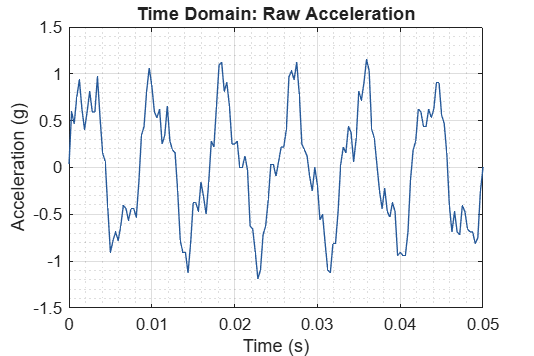

figure('Name', 'Vibration Analysis Pipeline', 'NumberTitle', 'off', ...
       'Position', [100 100 1200 800]);

% Zoomed raw time-domain signal
plot(t, a, 'Color', [0.15 0.35 0.60], 'LineWidth', 0.6);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Time Domain: Raw Acceleration');
xlim([0, min(0.05, duration)]);   % zoom to first 50ms to see waveform
grid on;
grid minor;

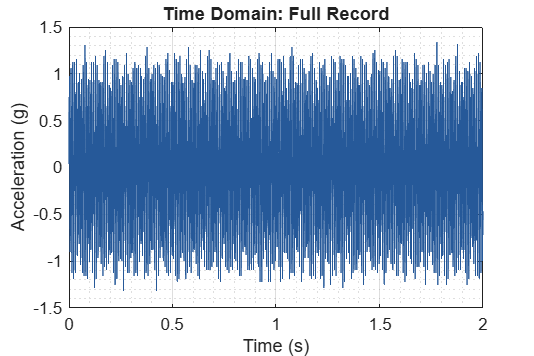


% Full raw time domain signal
plot(t, a, 'Color', [0.15 0.35 0.60], 'LineWidth', 0.4);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Time Domain: Full Record');
xlim([0, duration]);
grid on;
grid minor;

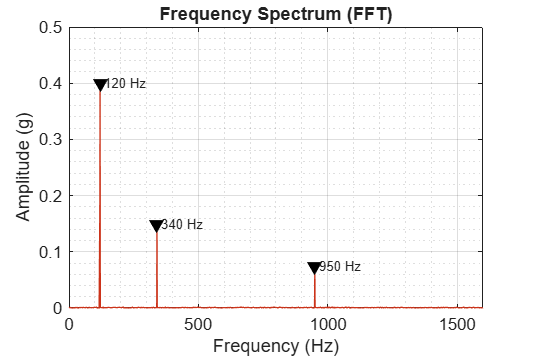


% FFT frequency spectrum
plot(f_axis, A_single, 'Color', [0.80 0.20 0.10], 'LineWidth', 0.8);
xlabel('Frequency (Hz)');
ylabel('Amplitude (g)');
title('Frequency Spectrum (FFT)');
xlim([0 fs/2]);
grid on;
grid minor;

% Annotate known injected peaks (remove these when using real data)
hold on;
[~, i1] = min(abs(f_axis - f1));
[~, i2] = min(abs(f_axis - f2));
[~, i3] = min(abs(f_axis - f3));
plot(f_axis(i1), A_single(i1), 'kv', 'MarkerFaceColor', 'k', 'MarkerSize', 7);
plot(f_axis(i2), A_single(i2), 'kv', 'MarkerFaceColor', 'k', 'MarkerSize', 7);
plot(f_axis(i3), A_single(i3), 'kv', 'MarkerFaceColor', 'k', 'MarkerSize', 7);
text(f1+15, A_single(i1), sprintf('%d Hz', f1), 'FontSize', 8);
text(f2+15, A_single(i2), sprintf('%d Hz', f2), 'FontSize', 8);
text(f3+15, A_single(i3), sprintf('%d Hz', f3), 'FontSize', 8);
hold off;

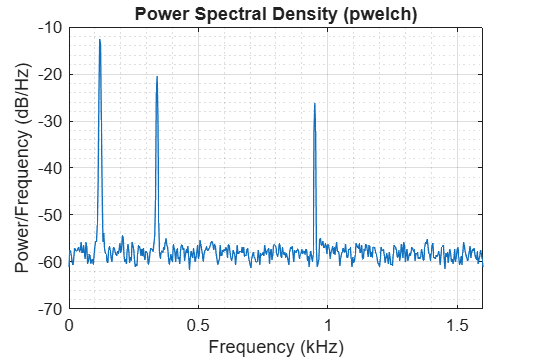


% PSD with pwelch
pwelch(a, hann(window_len), overlap, window_len, fs);
title('Power Spectral Density (pwelch)');
grid on;
grid minor;

## Peak Detection

Automatically identifies dominant frequency peaks in the spectrum, which is useful for quickly finding structural resonances without manual inspection.

% Find peaks with minimum prominence to filter noise floor
[peak_amps, peak_locs] = findpeaks(A_single, ...
    'MinPeakProminence', 0.05, ...          % minimum amplitude above local baseline (g)
    'MinPeakDistance',  round(10/df), ...   % minimum 10 Hz separation between peaks
    'SortStr', 'descend', ...
    'NPeaks', 10);                          % report top 10 peaks

peak_freqs = f_axis(peak_locs);

fprintf('Detected resonant peaks (sorted by amplitude):\n');

Detected resonant peaks (sorted by amplitude):


fprintf('  %-12s %-15s\n', 'Freq (Hz)', 'Amplitude (g)');

  Freq (Hz)    Amplitude (g)  


fprintf('  %s\n', repmat('-', 1, 27));

  ---------------------------



for k = 1:length(peak_freqs)
    fprintf('  %-12.1f %.4f\n', peak_freqs(k), peak_amps(k));
end

  120.0        0.4003
  340.0        0.1492
  950.0        0.0745


## Exports

Data from graphs is exported as `.csv` for ANSYS.

% FFT export
fft_table = table(f_axis', A_single, 'VariableNames', {'Frequency_Hz', 'Amplitude_g'});
writetable(fft_table, 'fft_export.csv');
fprintf('FFT exported to fft_export.csv\n');

FFT exported to fft_export.csv


% PSD export (using pwelch)
[psd_power, psd_freq] = pwelch(a, hann(window_len), overlap, window_len, fs);
psd_table = table(psd_freq, psd_power, 'VariableNames', {'Frequency_Hz', 'PSD_g2_per_Hz'});
writetable(psd_table, 'psd_export.csv');
fprintf('PSD exported to psd_export.csv\n');

PSD exported to psd_export.csv
